#### **ANALISIS DE RESPUESTA EN EL TIEMPO**

Como puede responder una señal exponencial

%syms t;
%y1=exp(-(2)*tf);pretty(y1)
%exp (-2 t);%Decreciente

%y2=exp(-(2)*tf);pretty(y2)
%exp (2 t); %Creciente

%flot(y1,[0 1],'r'),hold on,fplot(y2,[0 1],'b-.')
%legend


#### **HALLAR LOS POLOS DE UN SISTEMA DE SINUSOIDES POR EXPONENCIALES**

%EJEMPLO #1
G=tf(8,[1 2.8 4])

G =
 
         8
  ---------------
  s^2 + 2.8 s + 4
 
Continuous-time transfer function.



%roots([1 2.8 4]) %con esa forma podemos hallar las raices 
%directamente
pole(G) %aqui obtenemos los polos de el sistema

ans =   -1.4000 + 1.4283i
  -1.4000 - 1.4283i


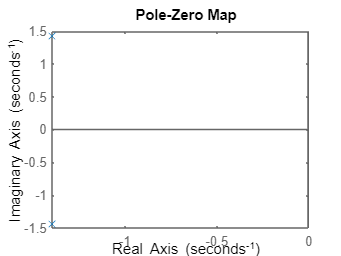

pzmap(G)%aqui podemos ver graficamente la ubicacion de polos y ceros

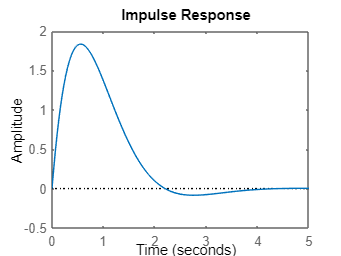

impulse(G)%Aqui obtenemos la grafica frente a un impulso


%EJEMPLO #2
G1=tf(32,[1 5.6 16])

G1 =
 
         32
  ----------------
  s^2 + 5.6 s + 16
 
Continuous-time transfer function.



pole(G1) %aqui obtenemos los polos de el sistema

ans =   -2.8000 + 2.8566i
  -2.8000 - 2.8566i


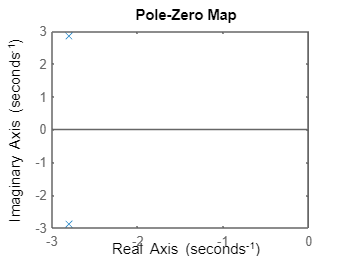

pzmap(G1)%aqui podemos ver graficamente la ubicacion de polos y ceros

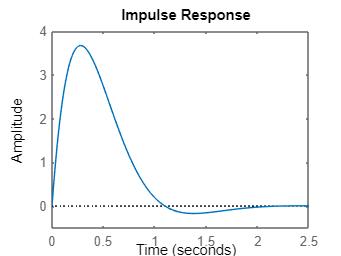

impulse(G1)%Aqui obtenemos la grafica frente a un impulso


%EJEMPLO #3
G2=tf(18,[1 -4.2 9])

G2 =
 
        18
  ---------------
  s^2 - 4.2 s + 9
 
Continuous-time transfer function.



pole(G2) %aqui obtenemos los polos de el sistema

ans =    2.1000 + 2.1424i
   2.1000 - 2.1424i


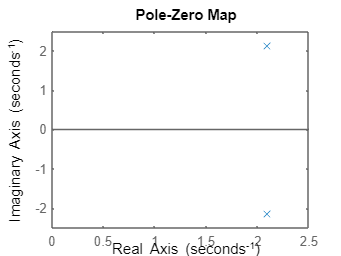

pzmap(G2)%aqui podemos ver graficamente la ubicacion de polos y ceros

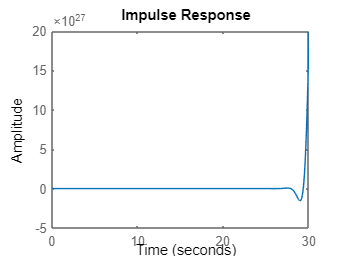

impulse(G2)%Aqui obtenemos la grafica frente a un impulso

#### SISTEMA CONTINUO 1.ORDEN

s=tf('s'); %Definimos s como una variable simbolica
G4=3/(3*s+1);%esta funcion de transferencia esta en constante de tiempo
zpk(tf(G4)) %para convertir la funcion de transferencia a ganancia polo cero

ans =
 
      1
  ----------
  (s+0.3333)
 
Continuous-time zero/pole/gain model.



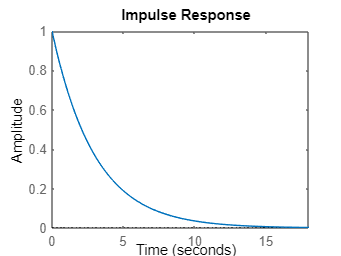

impulse(G4)%comprobamos la respuesta al impulso

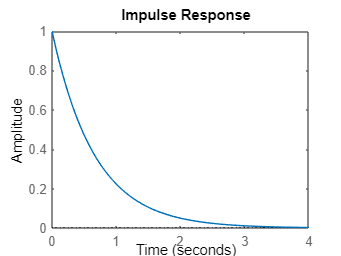


%EJEMPLO #2
H=1/(s+1.5); %esta funcion de transferencia esta en ganacia polo-cero
%convertirmos esta funcion de transferencia a constante de tiempo para
%saber el tao
impulse(H)

#### PORCENTAJES PARA TAO

% T0,T1,T2,T3,T4,T5
T=[0 1 2 3 4 5 ];
Y=exp(-T);
[T;Y]

ans =          0    1.0000    2.0000    3.0000    4.0000    5.0000
    1.0000    0.3679    0.1353    0.0498    0.0183    0.0067


%Como podemos apreciar
%cuando a pasado 1 TAO


#### RESPUESTA DE UN SISTEMA DE PRIMER ORDEN ,PARA UNA ENTRADA ESCALON

syms s Tau k a
ys=k/(s*a)*1/s;
pretty(ys)

  k
----
   2
a s



pretty(ilaplace(ys))

k t
---
 a



#### CUANTO DEMORA EL SIGUIENTE SISTEMA EN ALCANZAR LA ESTABILIDAD?

s=tf('s'); %Definimos s como una variable simbolica
G5=3/(6*s+2);
zpk(tf(G5))

ans =
 
     0.5
  ----------
  (s+0.3333)
 
Continuous-time zero/pole/gain model.



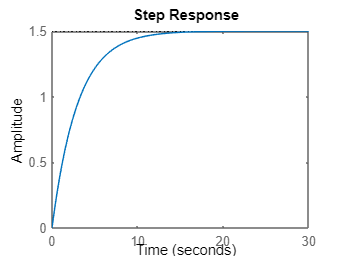

step(G5)%para comprobar utilizamos la grafica

#### HALLAR TIEMPO DE ESTABLECIMIENTO DE UNA FUNCION DE TRANSFERENCIA ANTE UNA RESPUESTA ESCALON

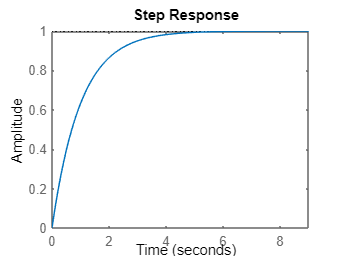

s=tf('s');
G6=1/(s+1);
step(G6)%veremos graficamente cuando se demora en estabilizarse

%una vez en la grafica ,damos click derecho--propiety---options -y
%cambiamos el valor de SHOW SETTLING TIME WITHIN al valor deseado,todo esto
%con el settling time ya activado en la grafica para poder viasualizar los
%cambios


# **SISTEMA CONTINUO DE 2DO ORDEN**

#### **hallar funcion de transferencia de de un diagrama de bloques **

%despues de simularla en simulink ,hacemos el llamamiento con el nombre
%dentro de las comillas
%[Num Den]=linmod('Bloques1');
%GT=tf(Num,Den)

#### SISTEMAS DE 2DO ORDEN (RESPUESTA AL PASO)

%Ejemplo #1
s=tf('s');          %Definir variable s
G7=tf(26,[1 2 26])  %Funcion de transferencia #1 

G7 =
 
        26
  --------------
  s^2 + 2 s + 26
 
Continuous-time transfer function.



G8=tf(5,[1 2 5])    %Funcion de tranferencia #2

G8 =
 
        5
  -------------
  s^2 + 2 s + 5
 
Continuous-time transfer function.



G9=tf(10,[1 2 10])  %Funcion de transferencia #3

G9 =
 
        10
  --------------
  s^2 + 2 s + 10
 
Continuous-time transfer function.



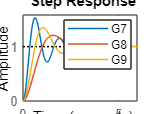

step(G7,G8,G9)      %Grafica de las 3 FT con respuesta al paso
legend

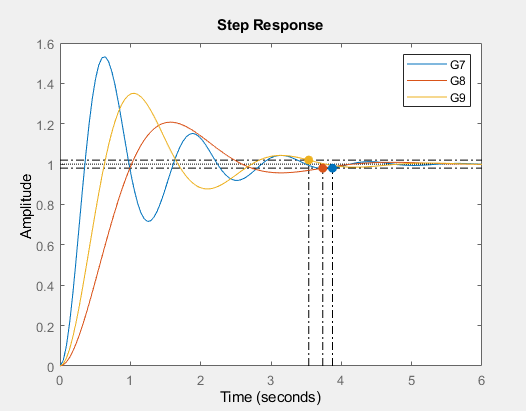

Para este ejemplo la parte real de todos ellos se mantiene constante (2s), al mantenerse este valor ,lo que define el cambio de la respuesta de el sistema es Wn

%Ejemplo #2
s=tf('s');          %Definir variable s
GA=tf(5,[1 2 5])  %Funcion de transferencia #1 

GA =
 
        5
  -------------
  s^2 + 2 s + 5
 
Continuous-time transfer function.



GB=tf(6.25,[1 3 6.25])    %Funcion de tranferencia #2

GB =
 
        6.25
  ----------------
  s^2 + 3 s + 6.25
 
Continuous-time transfer function.



GC=tf(4.64,[1 1.6 4.64])  %Funcion de transferencia #3

GC =
 
         4.64
  ------------------
  s^2 + 1.6 s + 4.64
 
Continuous-time transfer function.



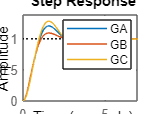

step(GA,GB,GC)      %Grafica de las 3 FT con respuesta al paso
legend

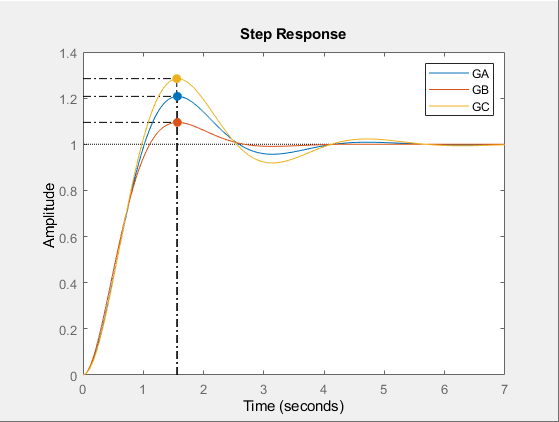

Aqui tenemos que la ubicacion de los polos reales es diferente y la posicion en Wn es casi la misma para los 3 sistemas

%Ejemplo #3
s=tf('s');          %Definir variable s
GD=tf(25,[1 5 25])  %Funcion de transferencia #1 

GD =
 
        25
  --------------
  s^2 + 5 s + 25
 
Continuous-time transfer function.



GE=tf(4,[1 2 4])    %Funcion de tranferencia #2

GE =
 
        4
  -------------
  s^2 + 2 s + 4
 
Continuous-time transfer function.



GF=tf(9,[1 3 9])  %Funcion de transferencia #3

GF =
 
        9
  -------------
  s^2 + 3 s + 9
 
Continuous-time transfer function.



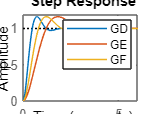

step(GD,GE,GF)      %Grafica de las 3 FT con respuesta al paso
legend

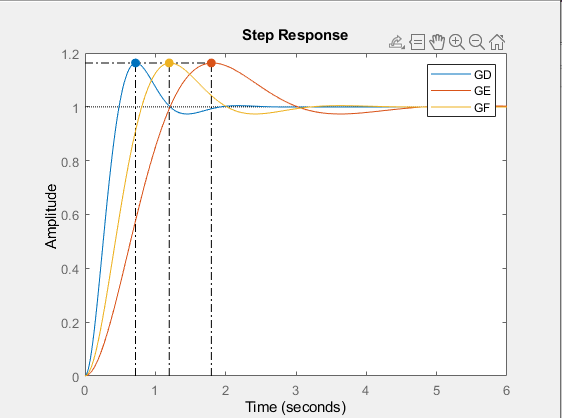asdasd

tienen el mismo sobre pico , pero su Wn es diferente siendo la de GE la mas pequeña por lo tanto responde mas lento y GD la de Wn  mas grande por lo tanto responde mas rapido

#### EJEMPLO PARA HALLAR LOS PARAMETROS CON LA GRAFICA Y CALCULOS

s=tf('s');  
A1=tf(337.5,[1 21 225])

A1 =
 
       337.5
  ----------------
  s^2 + 21 s + 225
 
Continuous-time transfer function.



pole(A1)

ans =  -10.5000 +10.7121i
 -10.5000 -10.7121i


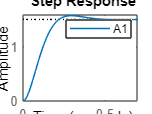

step(A1)
legend

%para este ejemplo nos pedian los siguiente parametros
%MAximo sobrepico
%tiempo de pico
%tiempo de establecimiento
%ubicacion de los polos en el eje real y imaginario
%al graficar con step y ver las caracterisitcas de la señal
%en PEAK RESPONSE  podemos ver :Maximo Sobrepico= OVERSHOOT 
% Tiempo de Pico en el mismo cuadro que es = At time
%Tiempo de establecimiento = "Settling time"
%y la ubicacion de los polos con "pole()".


# SISTEMAS DE ORDEN SUPERIOR

#### EJEMPLO EFECTO DE POLOS Y CEROS

s=tf('s');  
A2=tf(8,[1 1 4])

A2 =
 
       8
  -----------
  s^2 + s + 4
 
Continuous-time transfer function.



pole(A2)

ans =   -0.5000 + 1.9365i
  -0.5000 - 1.9365i


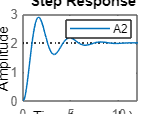

step(A2)
legend

%que le ocurre al sistema si le agrego un 0
